TN=tencom(y,u,r,init,varargin)

------------- Tensor completion given the inputs, outputs, TT-ranks, and TT initialization with scalar inputs

y = Outputs,

u = Inputs,

r = TT-ranks,

init = TT initialization.

Reference ---------

Fast and Accurate Tensor Completion with Tensor Trains: A System Identification Approach

clear all
% load housing
filename = 'C:\Users\Ridvanz\Desktop\Kim git\TTClassifier\DATASETS\housing.csv';
AA = readmatrix(filename);


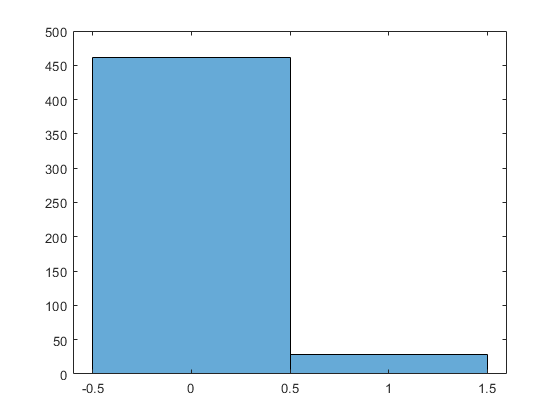


AA(AA(:,14)==50,:)=[];

histogram(AA(:,4)')

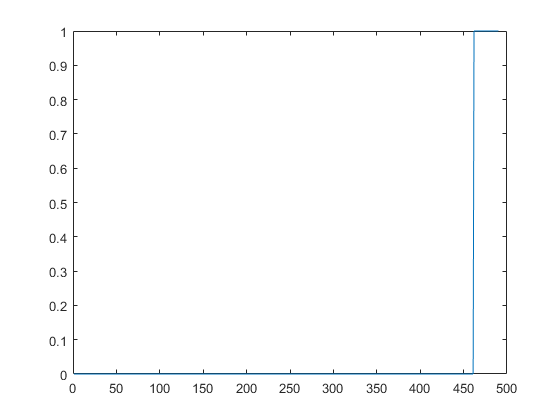


plot(sort(AA(:,4)'))

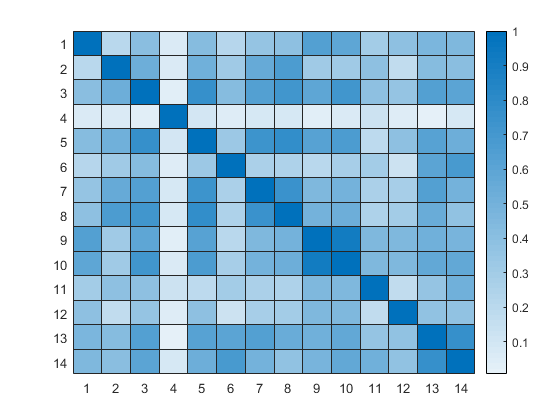

ans =   HeatmapChart with properties:

        XData: {14×1 cell}
        YData: {14×1 cell}
    ColorData: [14×14 double]

  Show all properties



heatmap(abs(corr(AA)))


inputamadre = normalize(AA);

max(abs(inputamadre))

ans =     9.7835    3.8910    2.4375    3.9830    2.7140    4.1101    2.3213    3.9299    1.6667    1.8029    2.8051    3.8381    3.5360    3.4537


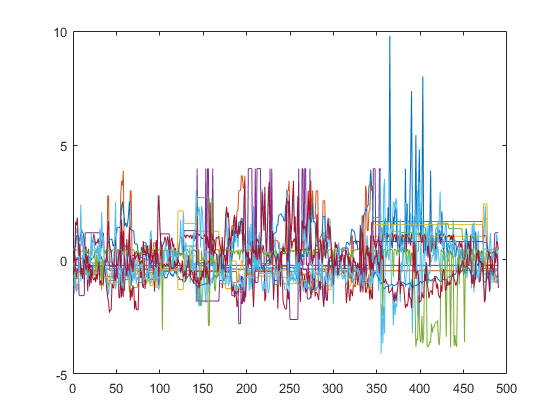


plot(inputamadre)

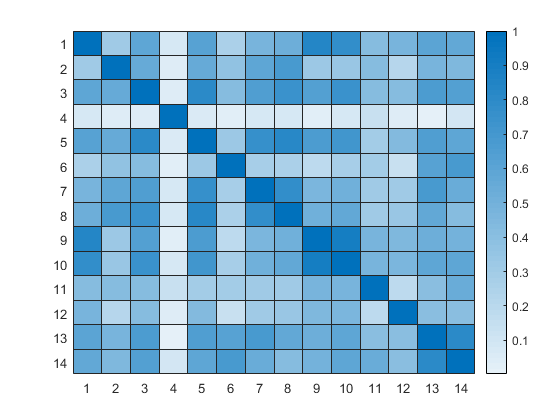

ans =   HeatmapChart with properties:

        XData: {14×1 cell}
        YData: {14×1 cell}
    ColorData: [14×14 double]

  Show all properties


gt = (1 + exp(-1*inputamadre)).^-1;

heatmap(abs(corr(gt)))

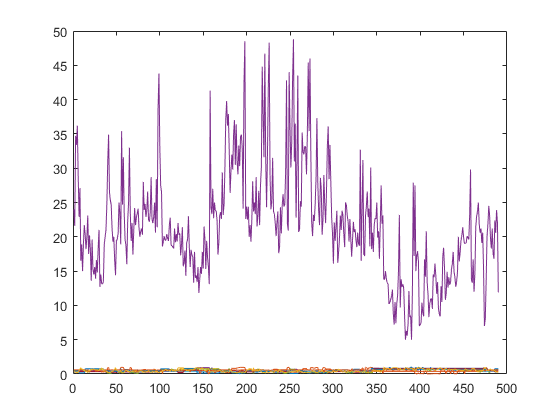

gt(:,4)=AA(:,4);
gt(:,end)=AA(:,end);
gt(:,[4 6 8])=[];

plot(gt);

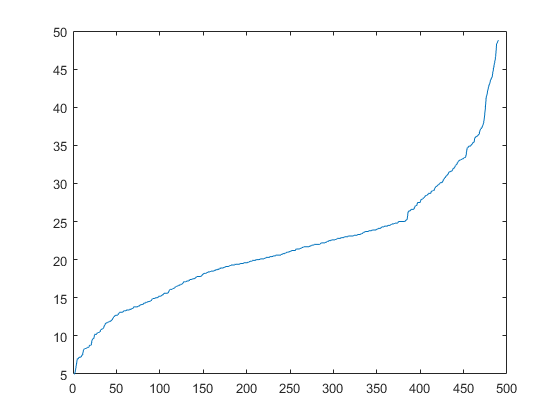

plot(sort(gt(:,end)'));

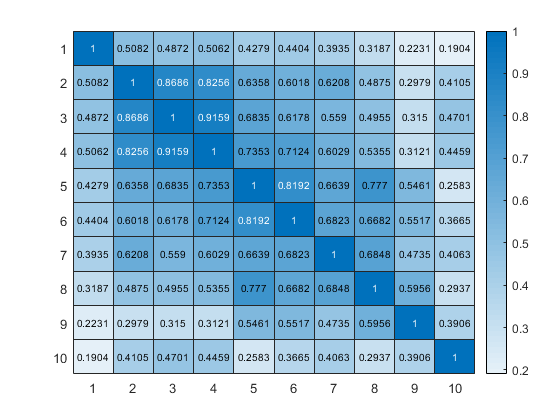


featurez=gt(1:end-51, 1:end-1);    tfeaturez=gt(end-50:end, 1:end-1);

y=gt(1:end-51, end);    tlabels=gt(end-50:end, end);

a = featurez;
Covz = corr(featurez);
Z= 1-abs(Covz);
[optima, distas] = findorder(Z);
featurez = featurez(:,optima');
Z = corr(featurez);
heatmap(abs(Z));


tfeaturez = tfeaturez(:,optima');


[N, d]=size(featurez); 

nn = 1;  %degree B-spline
knotintervals = 1;
nnn= knotintervals+nn;

bs = bspline([0:nn+1]);
M = flipud(bs.coefs)';

knotdist = 1/knotintervals;

indexes = floor(featurez/knotdist)+1;
indexes(indexes>knotintervals)= knotintervals;

inputs = (featurez/knotdist)-indexes+1;
for i=1:d
bn = inputs(:,i).^[nn:-1:0]*M;

u{i} = zeros(N,nnn);
for ii=1:N
   u{i}(ii,indexes(ii):indexes(ii)+nn) = bn(ii,:);
end
end



Pcount = (nnn)^d

Pcount = 1024

% gamma=((N/Pcount^4))
% gamma=0

R = nnn^2;
% R=6;
r=4*ones(1,d+1);
r(1) = 1; r(2)=nnn  ;  r(d-1)=nnn^2; r(d)=nnn; r(d+1)=1;

disp(r)

     1     2     4     4     4     4     4     4     4     2     1




n=nnn*ones(1,d);

init=cell(1,d);
    for i=1:d
        init{i}.core=randn(r(i),n(i),r(i+1));
        init{i}.core=(init{i}.core/(norm(init{i}.core(:))));
        init{i}.r(1)=r(i);
        init{i}.n = n(i);
        init{i}.r(2)=r(i+1);
    end


   
    
% function TN=tencom(y,u,r,init,varargin)

% 2018, Ching-Yun KO

% N=size(u{1},1);
% d=size(u,2);                 

for i=1:d
    n(i)=size(u{i},2);
end
  

for i=1:d
    TN.core{i}=init{i}.core;
    TN.n(i,:)=[init{i}.r(1),init{i}.n,init{i}.r(2)];
end


Vp=cell(1,d);
Vm=cell(1,d);

Vm{1}=ones(N,1);
Vp{d}=ones(N,1);

% initialize right-orthonormal cores with prescribed TN ranks
for i=d:-1:2
    Vp{i-1}=dotkron(Vp{i},u{i})*reshape(permute(TN.core{i},[3 2 1]),[r(i+1)*n(i),r(i)]); 
end

res1=[];
res2=[];
MAXITR = 5*d;

itr=1;                          % counts number of iterations
ltr=1;                          % flag that checks whether we sweep left to right
sweepindex=1;                   % index that indicates which TT core will be updated

gamma=0.001;
 tic
bbb=1;
% while itr<2 || ((e(itr) < e(itr-1)) && (itr < MAXITR) && e(itr) > THRESHOLD)
while itr<2 ||  (itr < MAXITR )
%     ---------------------updateTT-----------------;
            
nselect = floor(((itr+1)/MAXITR)^4*(N));
dataselect = randperm((N),nselect);
dataselect = 1:N;
    %         % first construct the linear subsystem matrix
        A=dotkron(Vm{sweepindex}(dataselect,:),u{sweepindex}(dataselect,:),Vp{sweepindex}(dataselect,:));
%         g=pinv(A'*A)*(A'*y(dataselect,:));
     
        D = eye(r(sweepindex)*(n(sweepindex))*r(sweepindex+1));        
        g=pinv(A'*A + gamma*D)*(A'*y(dataselect,:));
testoro(bbb) = g'*g;
bbb=bbb+1;
        if ltr
            % left-to-right sweep, generate left orthogonal cores and update vk1
            TN.core{sweepindex}=reshape(g,[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            [Q,R]=qr(reshape(g,[r(sweepindex)*(n(sweepindex)),r(sweepindex+1)])); 
            TN.core{sweepindex}=reshape(Q(:,1:r(sweepindex+1)),[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            TN.core{sweepindex+1}=reshape(R(1:r(sweepindex+1),:)*reshape(TN.core{sweepindex+1},[r(sweepindex+1),(n(sweepindex+1))*r(sweepindex+2)]),[r(sweepindex+1),n(sweepindex+1),r(sweepindex+2)]);
            Vm{sweepindex+1}=dotkron(Vm{sweepindex},u{sweepindex})*reshape(TN.core{sweepindex},[r(sweepindex)*n(sweepindex),r(sweepindex+1)]); % N x r_{i}
        else
            % right-to-left sweep, generate right orthogonal cores and update vk2
            TN.core{sweepindex}=reshape(g,[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            [Q,R]=qr(reshape(g,[r(sweepindex),(n(sweepindex))*r(sweepindex+1)])'); 
            TN.core{sweepindex}=reshape(Q(:,1:r(sweepindex))',[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            TN.core{sweepindex-1}=reshape(reshape(TN.core{sweepindex-1},[r(sweepindex-1)*(n(sweepindex-1)),r(sweepindex)])*R(1:r(sweepindex),:)',[r(sweepindex-1),n(sweepindex-1),r(sweepindex)]);
            Vp{sweepindex-1}=dotkron(Vp{sweepindex},u{sweepindex})*reshape(permute(TN.core{sweepindex},[3 2 1]),[r(sweepindex+1)*n(sweepindex),r(sweepindex)]); % N x r_{i-1}    

        end
    
   %     ---------------------updatesweep-----------------; 
     
                if ltr
                    sweepindex=sweepindex+1;
                    if sweepindex== d                
                        ltr=0;
                        timer=toc;
                    end
                else
                    sweepindex=sweepindex-1;
                    if sweepindex== 1                
                        ltr=1;
                        timer=toc;
                    end
                end
    
    
        % only check residual after 1 half sweep
        if (sweepindex==d) || (sweepindex==1) % half a sweep
            
            res1(itr)=norm(A*g-y(dataselect,:))^2/(nselect); % check residual
            res2(itr)=1*(g'*g);
           
            if (itr>4)
%                 if (res1(itr)<1) || (abs(res1(itr)-res1(itr-2))<1)
%                  disp(res1(itr))
%                  break;
%                  end
            end
            
            itr=itr+1; %update iteration
            
            disp(["iteration:" itr timer])
        end   

        
end  

    "iteration:"    "2"    "0.017665"

    "iteration:"    "3"    "0.035254"

    "iteration:"    "4"    "0.040747"

    "iteration:"    "5"    "0.044639"

    "iteration:"    "6"    "0.048614"

    "iteration:"    "7"    "0.053"

    "iteration:"    "8"    "0.056753"

    "iteration:"    "9"    "0.06152"

    "iteration:"    "10"    "0.064925"

    "iteration:"    "11"    "0.068517"

    "iteration:"    "12"    "0.07158"

    "iteration:"    "13"    "0.076133"

    "iteration:"    "14"    "0.079104"

    "iteration:"    "15"    "0.08233"

    "iteration:"    "16"    "0.085356"

    "iteration:"    "17"    "0.088995"

    "iteration:"    "18"    "0.094425"

    "iteration:"    "19"    "0.098234"

    "iteration:"    "20"    "0.10986"

    "iteration:"    "21"    "0.1139"

    "iteration:"    "22"    "0.11723"

    "iteration:"    "23"    "0.1207"

    "iteration:"    "24"    "0.12498"

    "iteration:"    "25"    "0.12988"

    "iteration:"    "26"    "0.13297"

    "iteration:"    "27

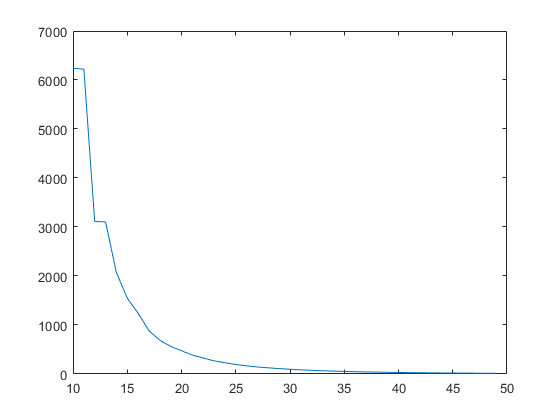

plot(res1)

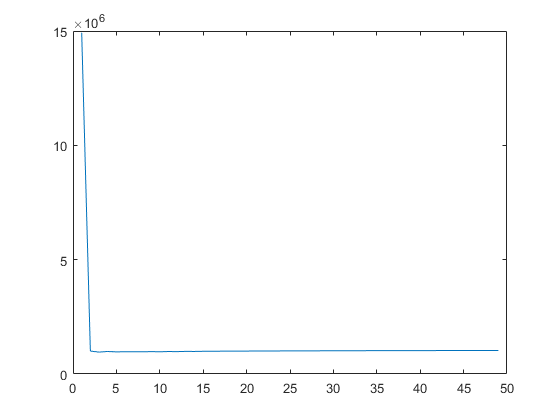

plot(res2)


[Nt, dt]=size(tfeaturez);

indexes = floor(tfeaturez/knotdist)+1;
indexes(indexes>knotintervals)= knotintervals;

inputs = (tfeaturez/knotdist)-indexes+1;
for i=1:dt
bn = inputs(:,i).^[nn:-1:0]*M;

ut{i} = zeros(Nt,nnn);
for ii=1:Nt
   ut{i}(ii,indexes(ii):indexes(ii)+nn) = bn(ii,:);
end
end

% [N, d]=size(featurez);

output=zeros(Nt,1);

G = TN.core;

for i = 1:length(G)
Gsize = [Nt size(G{i},1)  size(G{i},3)];
tempz = reshape(ut{i}*unfold(G{i},2), Gsize);
V{i} = permute(tempz, [2 3 1]);
end

output= zeros(Nt,1);

for jj=1:Nt   
f = (V{1});
f=1;
for i = 1:length(G)
f = f*V{i}(:,:,jj);
end
output(jj)=f';
end


[tlabels, id] = sort(tlabels);
output = output(id);

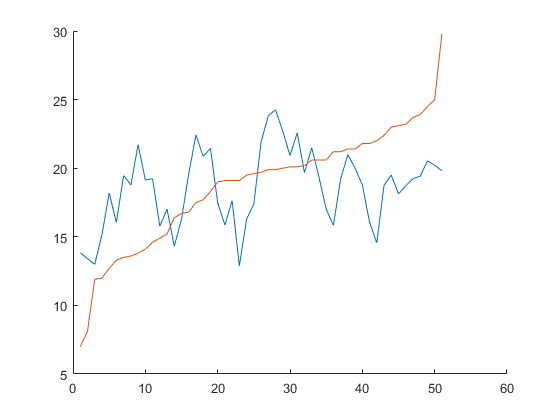


figure
hold on
plot(output)
plot(tlabels)
hold off

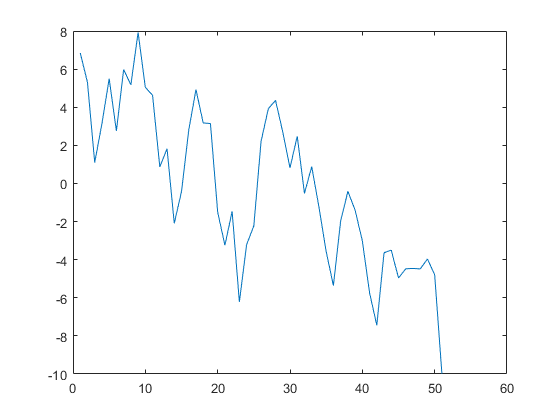

erboi = (output-tlabels);
plot(erboi)

pererror = sum(abs(erboi))/Nt

pererror = 3.5846

relerror = sum(abs(erboi)/sum(tlabels))

relerror = 0.1915

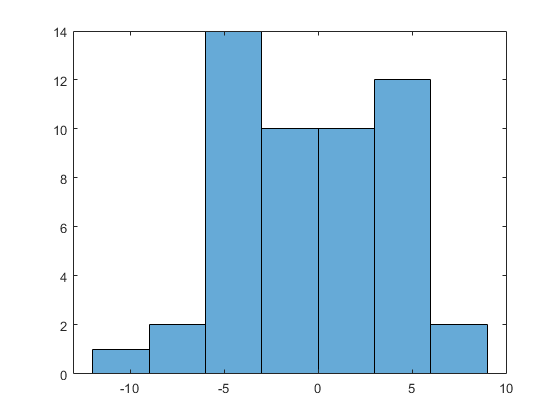

histogram((erboi)')


% % -------
% Vp=cell(1,d);
% Vm=cell(1,d);
% 
% Vm{1}=ones(N,1);
% Vp{d}=ones(N,1);
% 
% % initialize right-orthonormal cores with prescribed TN ranks
% for i=d:-1:2
%     Vp{i-1}=dotkron(Vp{i},u{i})*reshape(permute(TN.core{i},[3 2 1]),[r(i+1)*n(i),r(i)]); 
% end



